# Incremental PCA (II). Experimental images

In this script we compute two examples to demonstrate the performance of the incremental PCA algorithm, using two set of experimental fringe patterns. The first set is composed of 19 interferograms with a mask, while the second set is formed by 9 interferograms. In both cases, the results of the standard an incremental PCA are quite similar, showing the feasibility of the proposed incremental PCA phase demodulation.

@ 2021 Jose A. Gomez-Pedrero, Julio C. Estrada, Juan A. Quiroga, Jose Alonso and Javier Vargas

Disclaimer: This software is supplied without any guarantee or any support whatsoever.

## Example 1. Demodulation of experimental fringe patterns (I)

In this example, we will demodulate a set of N=19 experimental fringe patterns. These patterns do present a moderate amount of random noise. It also shows relatively low modulation and, finally, it is masked.

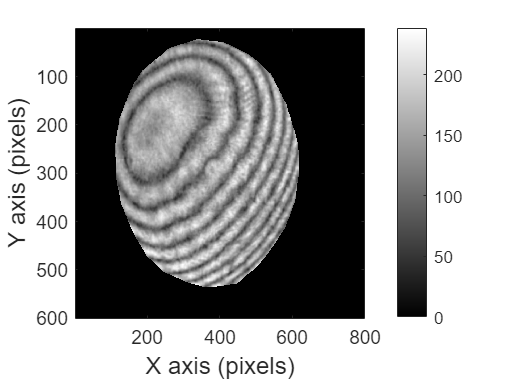

clear all;
% Load the experimental fringe pattern set
load('RealInt.mat','I2','Mask');
I = I2;
tam = size(I);

% Show the first a) and last b) fringe pattern of the set
% First fringe pattern
figure;
imagesc(I(:,:,1).*Mask); colormap("gray"); colorbar;
xlabel('X axis (pixels)','FontSize',12)
ylabel('Y axis (pixels)','FontSize',12)

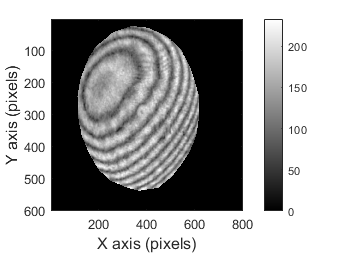


% Last fringe pattern
figure;
imagesc(I(:,:,end).*Mask); colormap("gray"); colorbar;
xlabel('X axis (pixels)','FontSize',12)
ylabel('Y axis (pixels)','FontSize',12)

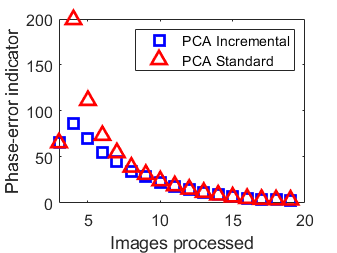


% Demodulate the fringe pattern using incremental PCA with quality
% parameter

% Initial operations
X = zeros(tam(1)*tam(2),3);
for k=1:3
    I1 = I(:,:,k).*Mask;
    X(:,k) = I1(:);
end
Qpar = zeros(1,tam(3)-3);
mu = mean(X,2);
X = bsxfun(@minus,X,mu);

% First iteration and mail loop
[U,D] = svd(X,'econ');
Qpar(1) = Compute_PCA_Q(D*D);
Gamma0 = 0.1; % Set the threshold value for the error-phase indicator
FLAG_OPT = true;
for k=4:tam(3)
   I1 = I(:,:,k).*Mask;
   I1 = I1(:);
   mu = mu*(k-1)/k + I1/k; % Updates the pixel-wise mean
   I1 = I1 - mu;
   [U,D]=IncrementalSKL(I1,U,D,3);
   Qpar(k-2) = Compute_PCA_Q(D*D);
   if(FLAG_OPT)
       % If the error phase indicator is bellow the 
       % threshold value, compute the phase 
       if(Qpar(k-2)<Gamma0)
           T = U*D; % Computes principal eigenvectors
           WPhi = -atan2(T(:,2),T(:,1));
           WPhi = reshape(WPhi,tam(1),tam(2)).*Mask;
           Nimg = k;
           FLAG_OPT = false;
       end
   end
end

% This code allows for computing the phase when the
% phase-error indicator is avobe threshold after 
% processing the whole set of images
if(FLAG_OPT)
    T = U*D; % Computes principal eigenvectors
    WPhi = -atan2(T(:,2),T(:,1));
    WPhi = reshape(WPhi,tam(1),tam(2)).*Mask;
end

% Compute standard PCA 
% Prepare the data matrix
X = zeros(tam(1)*tam(2),tam(3));
for k=1:tam(3)
    X(:,k) = reshape(I(:,:,k).*Mask,tam(1)*tam(2),1);
end
X = bsxfun(@minus,X,mean(X,2));
Dm1 = zeros(3,3,tam(3)-1);
Qpar1 = zeros(1,tam(3)-2);
for k=3:tam(3)
    [WPhi1,Mod,q1,q2,q3] = qcaDemod(I(:,:,1:k),3,Mask);
    Qpar1(k-2) = q3;
end

% Plot the evolution of the quality parameter
figure;
plot(3:19,100*Qpar,'sb','MarkerSize',10,'LineWidth',2);
hold on
plot(3:19,Qpar1,'^r','MarkerSize',10,'LineWidth',2);
xlabel('Images processed','FontSize',12);
ylabel('Phase-error indicator','FontSize',12);
legend('PCA Incremental','PCA Standard')
h = gca; set(h,'FontSize',12)
axis([3 20 0 200])

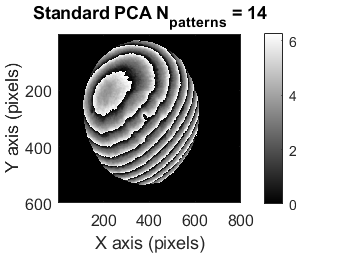


% Represent the wrapped phase obtained by the a) incremental
% and b) standard PCA at their optimum points
figure;
imagesc(mod(WPhi,2*pi).*Mask); colorbar; colormap('gray')
xlabel('X axis (pixels)','FontSize',12);
ylabel('Y axis (pixels)','FontSize',12);
title(['Standard PCA N_p_a_t_t_e_r_n_s = ' num2str(Nimg)]);
h = gca; set(h,'FontSize',12)

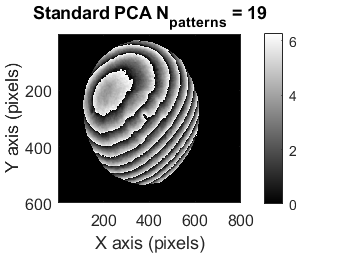


figure;
[WPhi1a, ErrPhi1] = adjustPiston(WPhi,WPhi1,Mask); 
imagesc(WPhi1a.*Mask); colorbar; colormap('gray')
xlabel('X axis (pixels)','FontSize',12);
ylabel('Y axis (pixels)','FontSize',12);
title(['Standard PCA N_p_a_t_t_e_r_n_s = ' num2str(tam(3))]);
h = gca; set(h,'FontSize',12)

## Example 2. Demodulation of experimental fringe patterns (II)

In this example, we will demodulate another experimental fringe pattern set composed by N = 9 interferograms. The patterns of this set present both random and periodical noise, with local low modulatoion areas, but, overall, fringe modulation is good

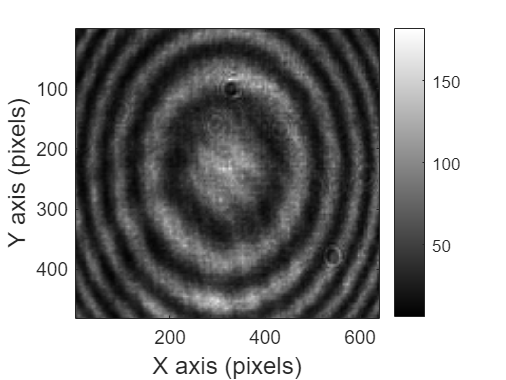

clear all;

% Load the experimental fringe pattern
load('ExperimentalResults.mat','I');
Mask = true(size(I,1),size(I,2));
tam = size(I);

% Show the first a) and last b) fringe pattern
% First fringe pattern
figure;
imagesc(I(:,:,1)); colormap("gray"); colorbar;
xlabel('X axis (pixels)','FontSize',12)
ylabel('Y axis (pixels)','FontSize',12)

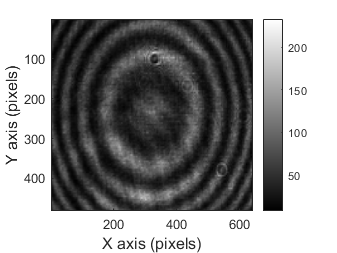


% Last fringe pattern
figure;
imagesc(I(:,:,end)); colormap("gray"); colorbar;
xlabel('X axis (pixels)','FontSize',12)
ylabel('Y axis (pixels)','FontSize',12)

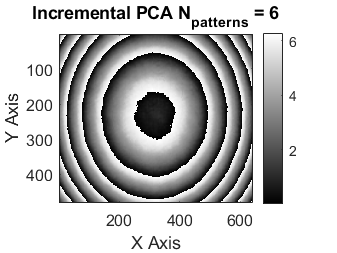


% Demodulate the fringe pattern using incremental PCA with quality
% parameter

% Initial operations
X = zeros(tam(1)*tam(2),3);
for k=1:3
    I1 = I(:,:,k).*Mask;
    X(:,k) = I1(:);
end
mu = mean(X,2);
X = bsxfun(@minus,X,mu);
Qpar = zeros(1,tam(3)-3);

% First iteration and mail loop
[U,D] = svd(X,'econ');
WPhiPCA = zeros(tam(1),tam(2));
Qpar(1) = Compute_PCA_Q(D*D);
Gamma0 = 0.1; % Set the threshold value for the error-phase indicator
FLAG_OPT = true;
for k=4:tam(3)
    I1 = I(:,:,k).*Mask;
    mu = ((k-1)*mu + I1(:))/k; % Updates image-wise mean
    [U,D]=IncrementalSKL((I1(:)-mu),U,D,3);
    Qpar(k-2) = Compute_PCA_Q(D*D);
    if(FLAG_OPT)
       % If the error phase indicator is bellow the 
       % threshold value, compute the phase 
       if(Qpar(k-2)<Gamma0)
           T = U*D; % Computes principal eigenvectors
           WPhi = -atan2(T(:,2),T(:,1));
           WPhi = reshape(WPhi,tam(1),tam(2)).*Mask;
           Nimg = k;
           FLAG_OPT = false;
       end
   end
end

% This code allows for computing the phase when the
% phase-error indicator is avobe threshold after 
% processing the whole set of images
if(FLAG_OPT)
    T = U*D; % Computes principal eigenvectors
    WPhi = -atan2(T(:,2),T(:,1));
    WPhi = reshape(WPhi,tam(1),tam(2)).*Mask;
end

% Phase demodulated phase with the Incremental PCA algorithm
figure;
imagesc(mod(WPhi,2*pi).*Mask); colorbar; colormap('gray')
title(['Incremental PCA N_p_a_t_t_e_r_n_s = ' num2str(Nimg)]);
xlabel('X Axis','FontSize',12);
ylabel('Y Axis','FontSize',12);
h = gca; set(h,'FontSize',12);

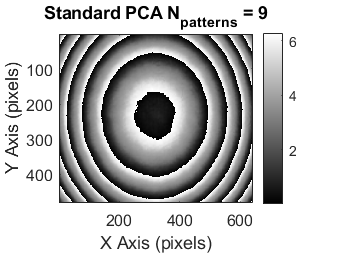


% Comparison with regular PCA

Qpar1 = zeros(1,tam(3)-2);
for k=3:tam(3)
    [WPhi1,Mod1,q1,q2,q3] = qcaDemod(I(:,:,1:k),3,Mask);
    Qpar1(k-2) = q3;
end

% Phase demodulated with the standard PCA
figure;
[WPhi1a,ErrPhi1] = adjustPiston(WPhi,WPhi1,Mask);
imagesc(WPhi1a.*Mask); colorbar; colormap('gray')
title(['Standard PCA N_p_a_t_t_e_r_n_s = ' num2str(tam(3))]);
xlabel('X Axis (pixels)','FontSize',12);
ylabel('Y Axis (pixels)','FontSize',12);
h = gca; set(h,'FontSize',12)

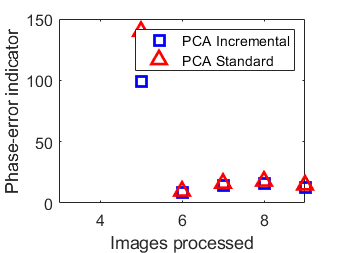


% Quality parameter evolution
figure;
plot(3:tam(3),100*Qpar,'sb','MarkerSize',10,'LineWidth',2);
hold on
plot(3:tam(3),Qpar1,'^r','MarkerSize',10,'LineWidth',2);
xlabel('Images processed','FontSize',12);
ylabel('Phase-error indicator','FontSize',12);
legend('PCA Incremental','PCA Standard')
h = gca; set(h,'FontSize',12)
axis([3 9 0 150])